# CSCI 5521: Introduction to Machine Learning (Spring 2019) Homework 0

Christopher White

February 6, 2019

## Problem 1.

### 1)

        
$$\begin{array}{l}
\frac{\textrm{d}}{\textrm{d}\mathbf{w}}{\left\|\mathbf{X}\;\mathbf{w}-\mathbf{y}\right\|}^2 =0\\
{\left\|\mathbf{X}\;\mathbf{w}-\mathbf{y}\right\|}^2 ={\left(\mathbf{X}\;\mathbf{w}-\mathbf{y}\right)}^{\prime } \;\left(\mathbf{X}\;\mathbf{w}-\mathbf{y}\right)\;\mathrm{where}{\;}^{\prime } \;\mathrm{is}\;\mathrm{conjugate}\;\mathrm{transpose}\\
{\left\|\mathbf{X}\;\mathbf{w}-\mathbf{y}\right\|}^2 =\left({\mathbf{w}}^{\prime } \;{\mathbf{X}}^{\prime } -{\mathbf{y}}^{\prime } \right)\left(\mathbf{X}\;\mathbf{w}-\mathbf{y}\right)\\
{\left\|\mathbf{X}\;\mathbf{w}-\mathbf{y}\right\|}^2 ={\mathbf{w}}^{\prime } {\;\mathbf{X}}^{\prime } \;\mathbf{X}\;\mathbf{w}-{\mathbf{y}}^{\prime } \mathbf{X}\;\mathbf{w}-{\mathbf{w}}^{\prime } {\mathbf{X}}^{\prime } \mathbf{y}+{\mathbf{y}}^{\prime } \;\mathbf{y}\\
{\mathbf{y}}^{\prime } \;\mathbf{X}\;\mathbf{w}={\mathbf{w}}^{\prime } \;{\mathbf{X}}^{\prime } \;\mathbf{y}\;\mathrm{because}\;\mathrm{each}\;\mathrm{side}\;\mathrm{is}\;\mathrm{a}\;1\mathrm{x1}\;\mathrm{matrix}\\
{\left\|\mathbf{X}\;\mathbf{w}-\mathbf{y}\right\|}^2 ={\mathbf{w}}^{\prime } {\;\mathbf{X}}^{\prime } \;\mathbf{X}\;\mathbf{w}-2\;{\mathbf{w}\;\mathbf{X}}^{\prime } \;\;\mathbf{y}+{\mathbf{y}}^{\prime } \;\mathbf{y}\\
-2\;\;{\mathbf{X}}^{\prime } \;\mathbf{y}+\frac{\textrm{d}}{\textrm{d}\mathbf{w}}{\mathbf{w}}^{\prime } \;{\mathbf{X}}^{\prime } \;\mathbf{X}\;\mathbf{w}=0
\end{array}$$


    It can be shown that ${\frac{\textrm{d}}{\textrm{d}\mathbf{w}}{{\mathbf{w}}^{\prime } \;\mathbf{X}}^{\prime } \;\mathbf{X}\;\mathbf{w}}^{\prime } =2\;{\mathbf{X}}^{\prime } \;\mathbf{X}\;\mathbf{w}$ from [here](http://global.oup.com/booksites/content/0199268010/samplesec3). Therefore,

        
$$\begin{array}{l}
-2{\mathbf{X}}^{\prime } \;\mathbf{y}+2\;{\mathbf{X}}^{\prime } \;\mathbf{X}\;\mathbf{w}=0\\
{\mathbf{X}}^{\prime } \;\mathbf{X}\;\mathbf{w}={\mathbf{X}}^{\prime } \;\mathbf{y}
\end{array}$$


    So,

        
$$\mathbf{w}={\left({\mathbf{X}}^{\prime } \;\mathbf{X}\right)}^{-1} \;{\mathbf{X}}^{\prime } \mathbf{y}$$


### 2)

        
$$\begin{array}{l}
\frac{\textrm{d}}{\textrm{d}\mathbf{w}}{\left\|\mathbf{Xw}-\mathbf{y}\right\|}^2 +\frac{\textrm{d}}{\textrm{d}\mathbf{w}}{\lambda \left\|\mathbf{w}\right\|}^2 =0\\
2\;{\mathbf{X}}^{\prime } \mathbf{Xw}-2{\mathbf{X}}^{\prime } \mathbf{y}+\frac{\textrm{d}}{\textrm{d}\mathbf{w}}\lambda {\left\|\mathbf{w}\right\|}^2 =0
\end{array}$$


    The $\mathbf{w}$is a vector so,

        
$$\begin{array}{l}
\frac{\textrm{d}}{\textrm{d}w_i }{\left\|\mathbf{w}\right\|}^2 =\sum_{j=1}^m \frac{\textrm{d}}{\textrm{d}w_i }w_j^2 =\frac{\textrm{d}}{\textrm{d}w_i }w_i^2 =2w_i \\
\frac{\textrm{d}}{\textrm{d}\mathbf{w}}{\left\|\mathbf{w}\right\|}^2 =2\mathbf{w}
\end{array}$$


    Therefore,

        
$$\begin{array}{l}
2{\mathbf{X}}^{\prime } \mathbf{Xw}-2{\mathbf{X}}^{\prime } \mathbf{y}+2\lambda \mathbf{w}=0\\
\left({\mathbf{X}}^{\prime } \mathbf{X}+\lambda \mathbf{I}\right)\mathbf{w}={\mathbf{X}}^{\prime } \mathbf{y}\\
\mathbf{w}={\left({\mathbf{X}}^{\prime } \mathbf{X}+\lambda \mathbf{I}\right)}^{-1} {\mathbf{X}}^{\prime } \mathbf{y}
\end{array}$$


### Problem 2.

#### 1)

        
$$\begin{array}{l}
\mathrm{Pr}\left(H,H,T,T,H\right)=p*p*\left(1-p\right)*\left(1-p\right)*p=p^3 -2p^4 +p^5 \\
\mathrm{ln}\left(\mathrm{Pr}\left(H,H,T,T,H\right)\right)=3\mathrm{ln}\left(p\right)+2\mathrm{ln}\left(1-p\right)
\end{array}$$


#### 2)

    a) $\mathrm{Pr}\left(\left\lbrace H,H,T,T,H\right\rbrace ,p=\frac{1}{2}\right)=\mathrm{Pr}\left(\left\lbrace H,H,T,T,H\right\rbrace |p=\frac{1}{2}\right)*\mathrm{Pr}\left(p=\frac{1}{2}\right)=\frac{1}{2^6 }$

    b) $\begin{array}{l}
\mathrm{Pr}\left(\left\lbrace H,H,T,T,H\right\rbrace ,p=\frac{2}{3}\right)=\mathrm{Pr}\left(\left\lbrace H,H,T,T,H\right\rbrace |p=\frac{2}{3}\right)*\mathrm{Pr}\left(p=\frac{2}{3}\right)\\
={\left(\frac{2}{3}\right)}^3 *{\left(\frac{1}{3}\right)}^2 *\frac{1}{2}=\frac{8}{486}
\end{array}$

#### 3)  

    Assume $p\ge 0$

        
$$\frac{\textrm{d}}{\textrm{d}p}\mathrm{ln}\left(\mathrm{Pr}\left(H,H,T,T,H\right)\right)=\frac{\textrm{d}}{\textrm{d}p}\left(3\mathrm{ln}\left(p\right)+2\mathrm{ln}\left(1-p\right)\right)=3\left(\frac{1}{p}\right)-2\left(\frac{1}{1-p}\right)$$


    The first derivative can be set to zero,

        
$$\begin{array}{l}
\frac{\textrm{d}}{\textrm{d}p}\mathrm{ln}\left(\mathrm{Pr}\left(H,H,T,T,H\right)\right)=0\\
\frac{3}{p}-\frac{2}{1-p}=\frac{3-3p-2p}{p\left(1-p\right)}=\frac{3-5p}{p\left(1-p\right)}=0\\
3-5p=0\\
p=\frac{3}{5}
\end{array}$$


    Thus p=3/5 is the maximum likelihood. So, the probability of H,H,T,T,H is:

        
$$\mathrm{Pr}\left(H,H,T,T,H\right)={\left(\frac{3}{5}\right)}^3 *{\left(\frac{2}{5}\right)}^2 =\frac{108}{3125}\approx 0\ldotp 03456$$


### Problem 3.

#### 1)

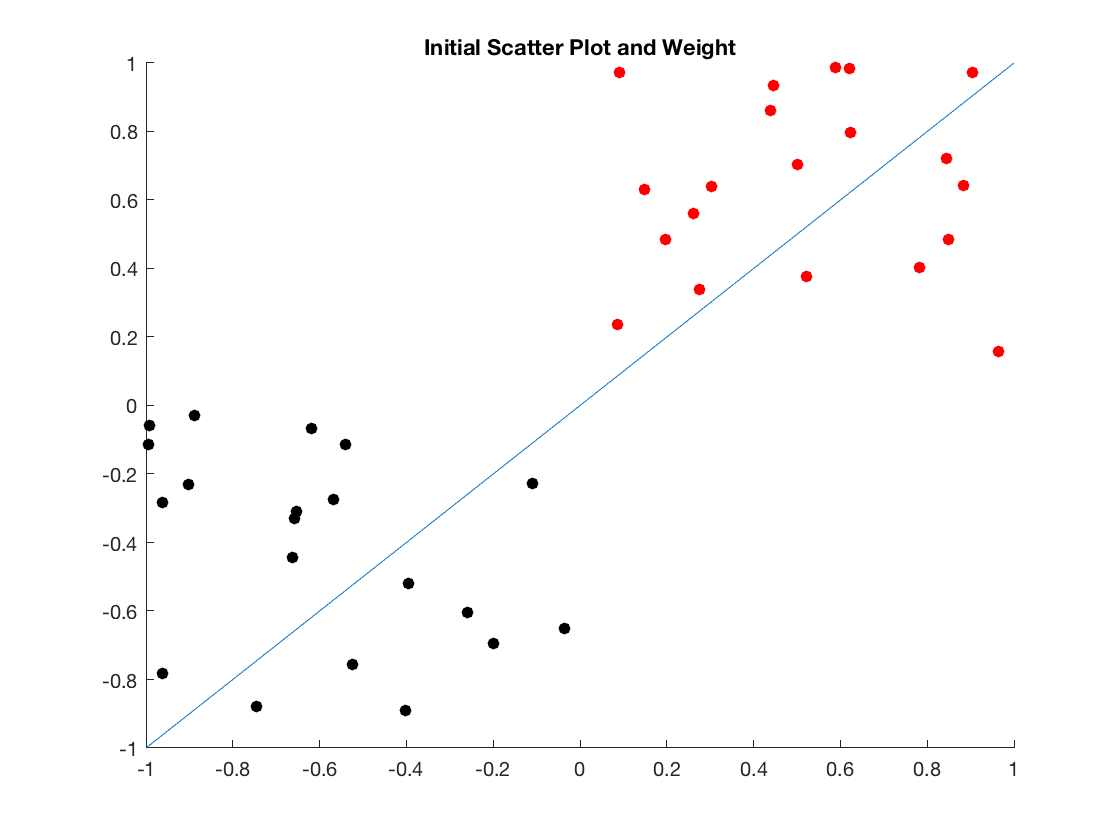

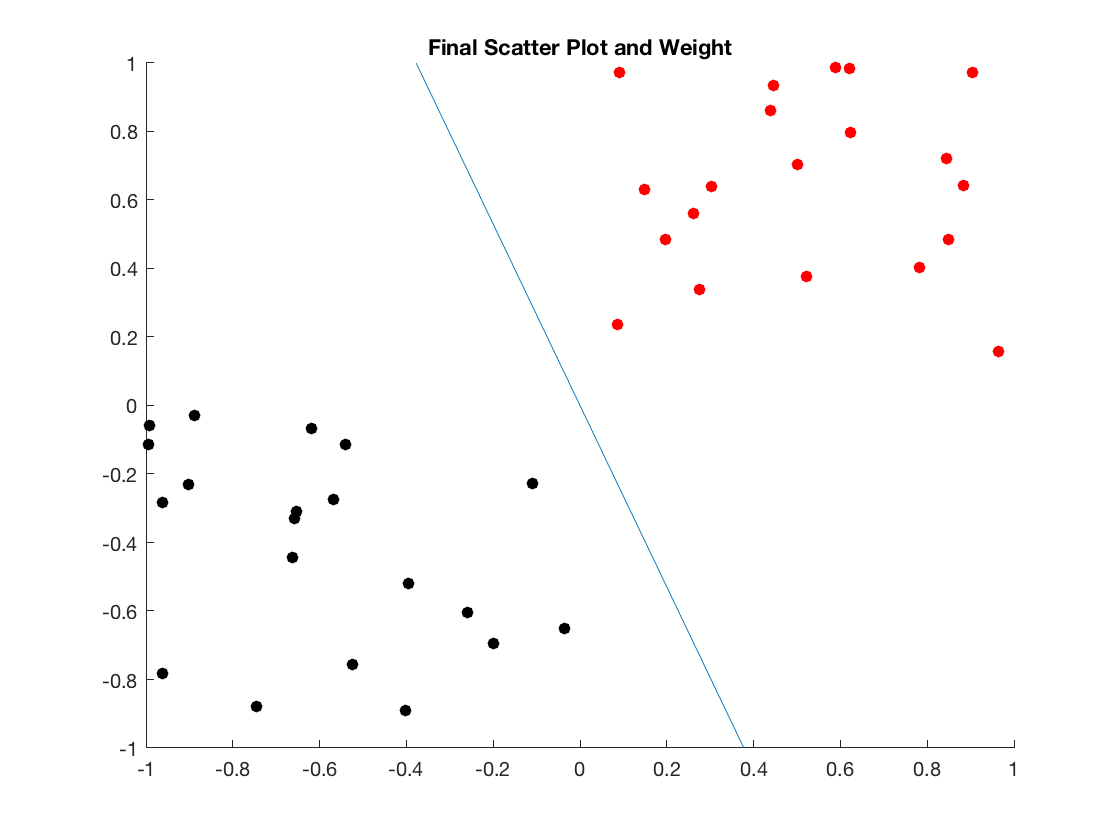

w =     1.4524
    0.5484


step = 2

load data1.mat
w0 = [1;-1];
[w,step] = MyPerceptron(X,y,w0)

       The data took 2 interations to converge.

#### 2)

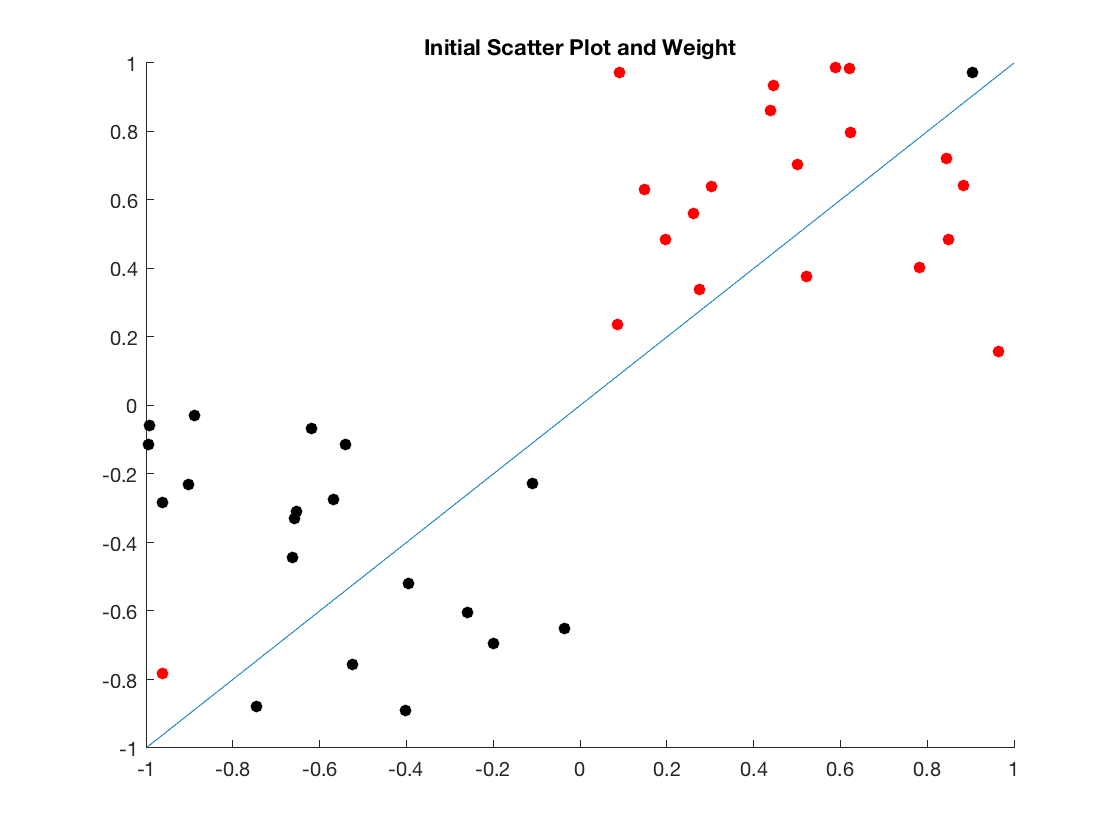

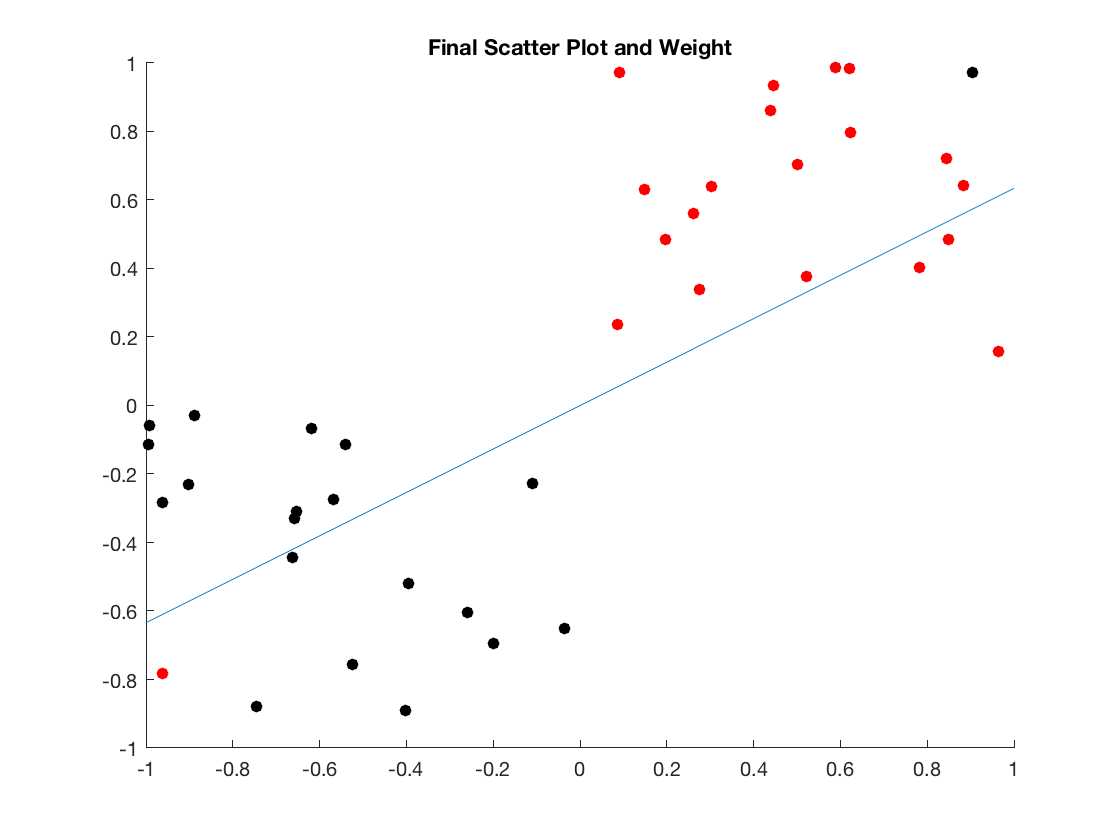

w =     0.1225
   -0.1932


step = 51

load data2.mat
w0=[1;-1];
[w,step] = MyPerceptron(X,y,w0)

    The code was not able to converge after 50 iterations so it terminated. The reason it didn't converge was that there are data points that will always be on the wrong side of the line. And the error is just a discrete count and therefore cannot reach zero in this dataset.

load data2.mat
[m,n]=size(X);
f=[zeros(n,1);ones(m,1)]; % transform problem into a standard LP
A1=[X.*repmat(y,1,n),eye(m,m)];
A2=[zeros(m,n),eye(m,m)];
A=-[A1;A2];
b=[-ones(m,1);zeros(m,1)];
x = linprog(f,A,b);% solve LP


Optimal solution found.



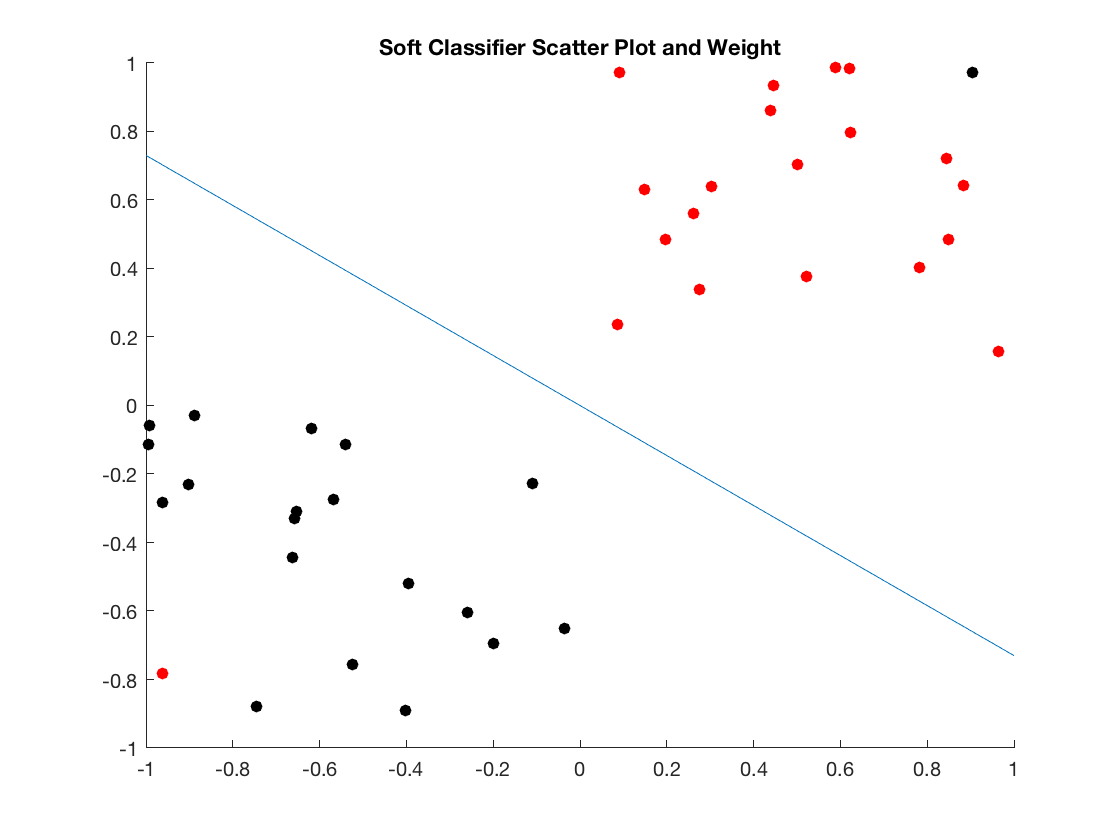

w=x(1:n);% return varible w

figure;
map = [0 0 0
        1 0 0];
colormap(map);
scatter(X(:,1),X(:,2),[],y,'filled');
xplt = xlim;
yset = ylim;
yplt = -w(1)*xplt/w(2);
line(xplt,yplt);
ylim(yset);
title('Soft Classifier Scatter Plot and Weight');